Number_of_Qubits = 1;
Number_of_Steps = 100;
Step_size = 0.000000001;
Number_of_walks = 10000;
Precision = 0.01;

Walk = Random_Walk(Number_of_Qubits, Number_of_Steps, Step_size, Number_of_walks, Precision)

Walk =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0

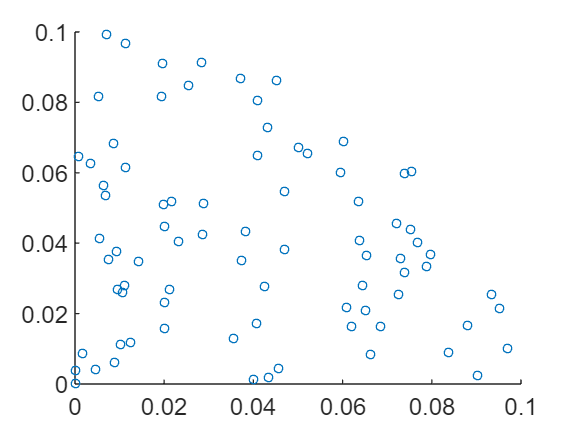

%Eliminate all zeros so just Successful walks remain??? 'any()'

% Plotting for Sanity Check (Only use for 2 dimensions) 
X = zeros;
Y = zeros;
 
for i = 1:2:2*(Number_of_walks + 1)
  if any(Walk, "all") == 1
    X = [X Walk(i)];
    Y = [Y Walk(i+1)];
  end
end 

scatter(X,Y, 10)

function RWV = Random_Walk_Vector(Dimensions)

    Local_Vector = randn(Dimensions,1);
    Summated_Vector = zeros(Dimensions,1);
    RWV = zeros(Dimensions,1);

    for m = 1:Dimensions

    Summated_Vector = Summated_Vector + Local_Vector(m)^2 ;

    end

    for n = 1:Dimensions

        RWV(n) = local_Vector(n)/sqrt(Summated_Vector);
    end

end 

function MGF = Metric_Generating_Function(Dimensions, First_State);

Local_Affine_Coordinates = zeros(Dimensions,1);
Absolute_Value_Affine_Coordinates = zero; 
FS_Metric_Matrix = zeros(Dimensions, Dimensions);

    for l = 1:Dimensions
    
        Local_Affine_Coordinates(l) = First_State(l)/First_State(1);
    
    end

    for m = 1:Dimensions
    
        Absolute_Value_Affine_Coordinates = Absolute_Value_Affine_Coordinates + Local_Affine_Coordinates(m)^2;
    end 

    for n = 1:Dimensions

        FS_Metric_Matrix(n,n) = 1 +  Absolute_Value_Affine_Coordinates^2 - Local_Affine_Coordinates(n)^2;

        for o = 2:dimensions 

            FS_Metric_Matrix(o,n) = -1*Local_Affine_Coordinates(n)*Local_Affine_Coordinates(o);
            FS_Metric_Matrix(n,o) = FS_Metric_Matrix(o,n);
        
        end
    
    end

    MGF = 1/(1+Absolute_Value_Affine_Coordinates^2)^2*FS_Metric_Matrix;
end



function V = Step_Generator(Step_Size,Dimensions, First_State)

    

    

end

function R = Random_Walk(Number_of_Qubits, Number_of_Steps, Step_size, Number_of_walks, Precision)

    Dimension_of_Hilbert_Space = 2^(Number_of_Qubits);
    Successful_Walks = zeros(Dimension_of_Hilbert_Space*Number_of_walks, Number_of_Steps);
   
    for n = 1:Dimension_of_Hilbert_Space:Dimension_of_Hilbert_Space*(Number_of_walks+1)

    State_Vectors = zeros(Dimension_of_Hilbert_Space, Number_of_Steps);
    Initial_State = rand(Dimension_of_Hilbert_Space,1);

    State_Vectors(:,1) = Initial_State;

        for t = 2:Number_of_Steps

            State_Vectors(:,t) = State_Vectors(:,t-1) + Step_Generator(Step_size,Dimension_of_Hilbert_Space);

        end 

        Final_Distance = acos(dot(State_Vectors(:,1), State_Vectors(:,Number_of_Steps)));

      if abs(pi/2 - Final_Distance) <= Precision
          
          for j = 1:Dimension_of_Hilbert_Space
          Successful_Walks(n-1+j,:) = State_Vectors(j,:);
          end
      end 
    end

    R = Successful_Walks;   
end